load burgers_data_R10.mat a u

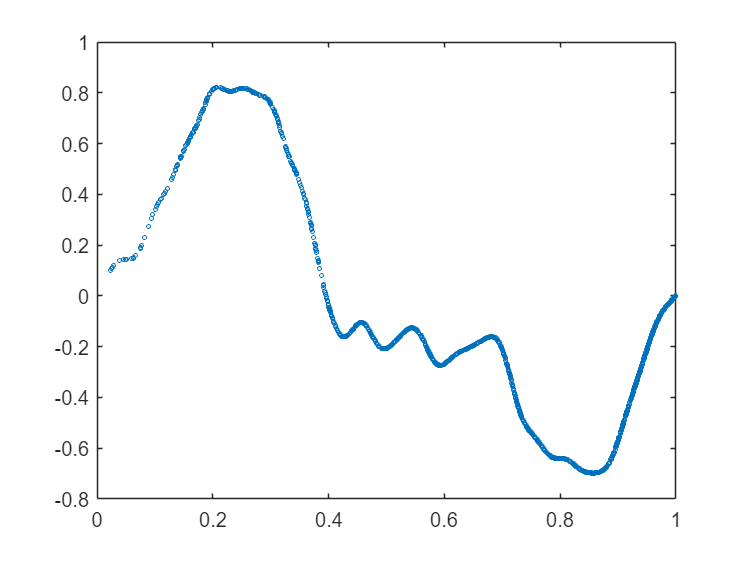

grid = linspace(0,1,8192+1);
grid = grid(1:end-1);

k = 100; % p(x) ~ kx+1 (k>0), k(x-1)+1 (k<0)

num_data = 2000;
N = 2048;
if k==0
    F_inv = @(u) u;
elseif k>0
    F_inv = @(u) (sqrt(1+k*(k+2)*u)-1)/k;
elseif k<0
    F_inv = @(u) 1-(sqrt(1-k*(-k+2)*u)-1)/(-k);
end
grid_interp = F_inv(rand(num_data,N));
% plot(grid_new(1,:),ones(1,N),'*')    
% histogram(grid_interp(1,:), 'Normalization', 'probability')

u_interp = zeros(num_data,N);
a_interp = zeros(num_data,N);
elems_list = zeros(num_data,N-1,1+2);
for i=1:num_data
    u_interp(i,:) = interp1(grid, u(i,:), grid_interp(i,:), 'spline').';
    a_interp(i,:) = interp1(grid, a(i,:), grid_interp(i,:), 'spline').';
    [sorted_grid, sort_idx] = sort(grid_interp(i,:));
    elements = [1:N-1; 2:N]';  %N-1,2
    elems_list(i,:,2:3) = sort_idx(elements);
    elems_list(i,:,1) = 2*ones(1,N-1);
end

% 
% grid_plot = grid_interp(1,:);
% for i = 1:N-1
%     plot(grid_plot(elems_list(1, i, 2:3)), [0,0], '-o', 'MarkerFaceColor', 'b');
%     hold on
% end
% hold off
% axis([min(grid_plot) max(grid_plot) -0.1 0.1]); % 调整y轴范围以便更好地查看线段
idx = 5;
plot(grid_interp(idx,:),a_interp(idx,:),'o','MarkerSize',2)
hold off

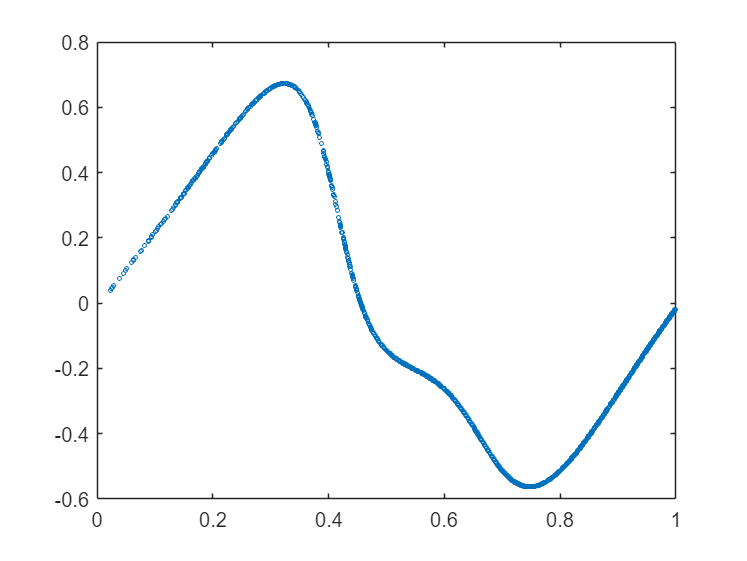

plot(grid_interp(idx,:),u_interp(idx,:),'o','MarkerSize',2)



% plot(grid_interp(1,:),zeros(1,N),'o','MarkerSize',0.01)
% % plot(grid,u(1,:),'o','MarkerSize',1)
% hold off

max_nnodes = N;
nodes_list = reshape(grid_interp,[size(grid_interp),1]);
elems_list;

features_list = cat(3,a_interp,u_interp);
filename = sprintf('burgers_k%.e_N%.f.mat', k,N);
save(filename, 'max_nnodes', 'nodes_list', 'elems_list', 'features_list');